# 2. DIGITAL FILTER DESIGN

## 2.1 Analysis of FIR-GLP filters obtained by classical windows. 

What mathematical expression studied in the course implement impulsopb.m?

%function h=impulsopb(M,Wc,ventana)

%n = 0:M;                                % vector de indice temporal
%n = n+10^(-10);                         % evita división por cero para n=0
%hr = sin(Wc*pi*(n-M/2))./(pi*(n-M/2));  % retardo de la respuesta ideal
%h=hr.*ventana';   


$$h\left\lbrack n\right\rbrack =\frac{\mathrm{sin}\left(\omega_c \pi \left(n-\alpha \right)\right)}{\pi \left(n-\alpha \right)}$$


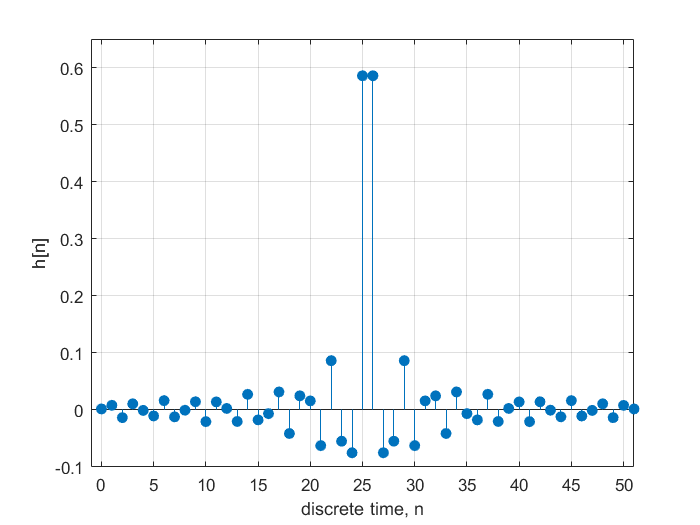

% analizaFIR
M=51; 
n =0:M;
wc=0.4*pi;
ventana = rectwin(M+1);
h=impulsopb(M,wc,ventana);
figure;stem(n,h,'filled');xlabel('discrete time, n'); ylabel('h[n]');axis([-1 M -0.1 0.65]);grid

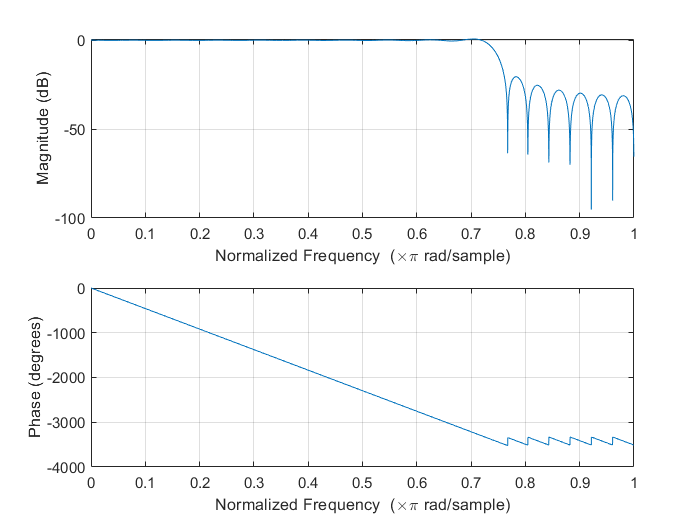

figure;freqz(h,1,4096)

Check that the impulse response and the frequency response are as expected. 


$$\begin{array}{l}
\alpha =\frac{M}{2}=\frac{51}{2}\approx 26\\
\mathrm{Att}=21\;\mathrm{dB}\\
\mathrm{bandwidth}=\omega_s -\omega_p =\frac{1\ldotp 81\pi }{M}=0\ldotp 1115
\end{array}$$


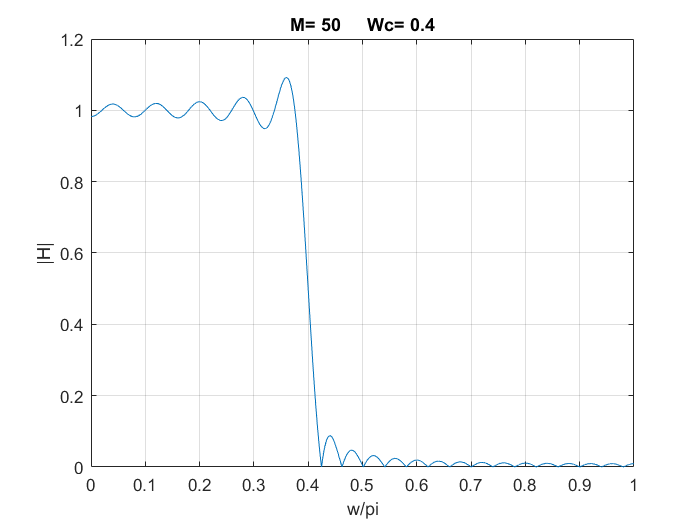

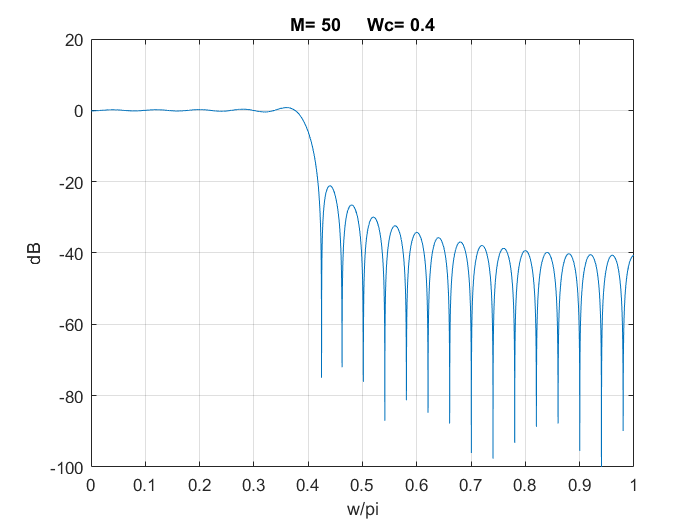

practica21

3. Using a zoom on the plot check that the maximum ripple in both bands agrees with the theoretical value: 

Theoretical at in the reject band (dB) -21

Attenuation in the reject band according to the plot(dB) -21.16

Theoretical attenuation in the pass band (dB) 0.75

Attenuation in the pass band according to the plot (dB) 0.76

4. Change in parametros21.m the value M=100. Run again practica21.m Does the ripple level change? Does the transition band width change? Justify your answer according to the theory. 

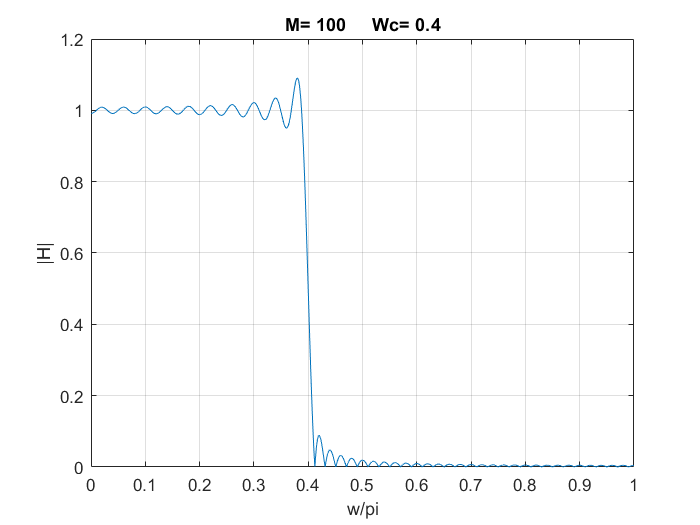

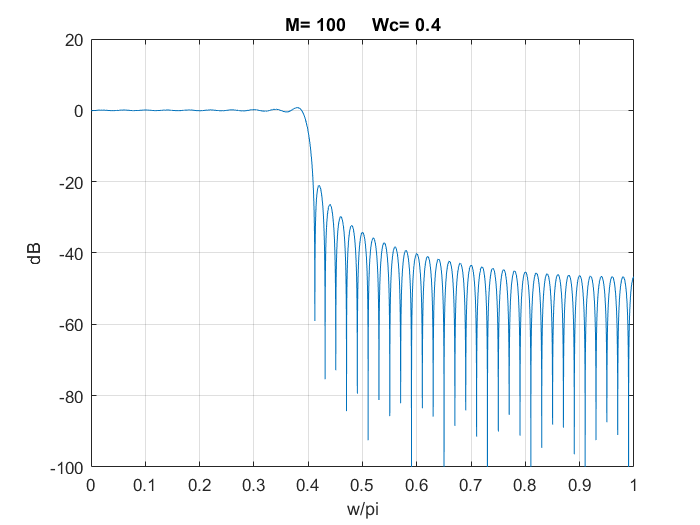

practica21

Does the ripple level change? No

Does the transition bandwidth change? Yes, by a factor of $\frac{1\ldotp 81\pi }{M}=0\ldotp 05686$

Set again the initial parameters and change the window to Hamming. Run again practica21

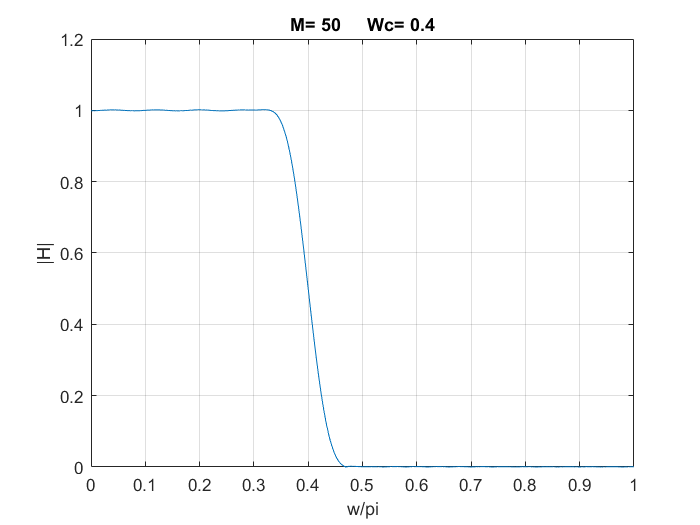

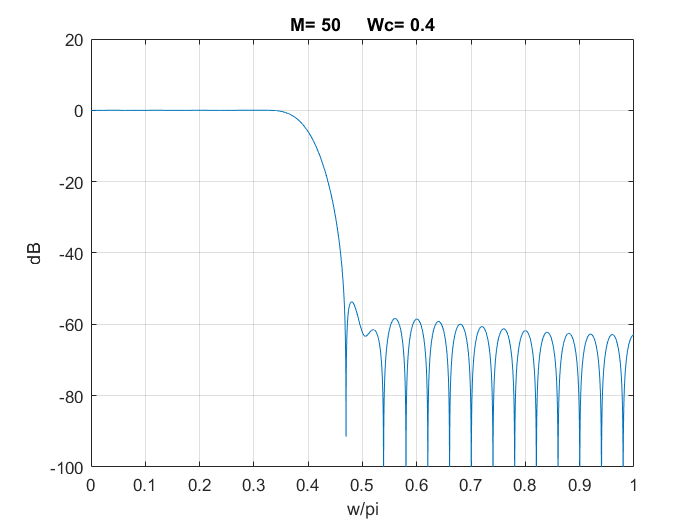

practica21

#### 5. Using zoom over the plot, verify that the maximum ripple in the attenuation band is that predicted by theory. 

Ripple in the attenuation band according to the theory (dB): 53 

Ripple in the attenuation band according to the plot (dB): 53.67

#### 6. Has the ripple changed when compared with the rectangular window? Has the transition bandwidth changed? Justify your answer. 

Has the ripple changed? Yes, now it's narrower. 

Has the transition bandwidth changed? Yes, now it follows the rule: $\frac{6\ldotp 6\pi }{M}=0\ldotp 4147$, which makes it wider. 

## 2.2 Design of FIR-GLP filters using classical windows

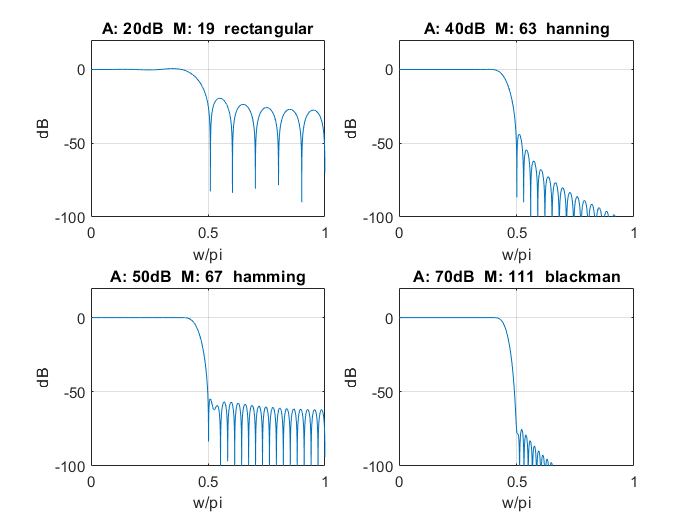

practica22

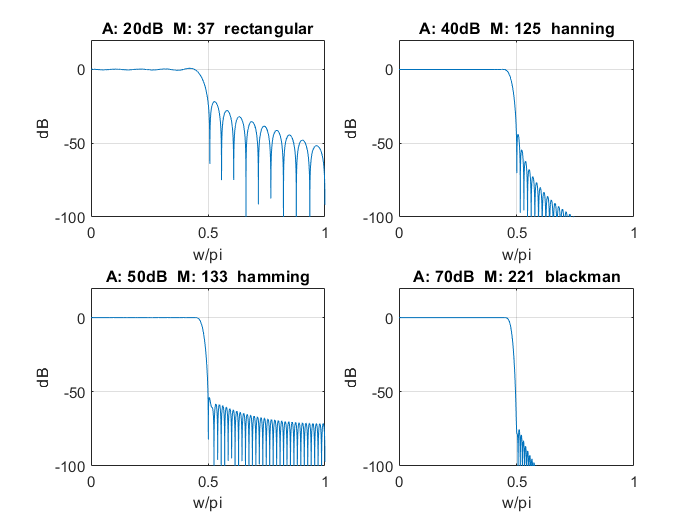

practica22

#### 7. Annotate the value of M obtained in each case. What is the effect on M of a change of $\omega_p$to $0\ldotp 45\pi$? Justify your answer.

Effect on M (Increase/Decrease): [19,63,67,111]-> [37,40,133,221] It has significantly increased. 

They are proportional. $M=\frac{k\pi }{\omega_s -\omega_p }$ where k depends on the type of filter.

## 2.3 Design of a FIR-GLP filters by the Kaiser method.

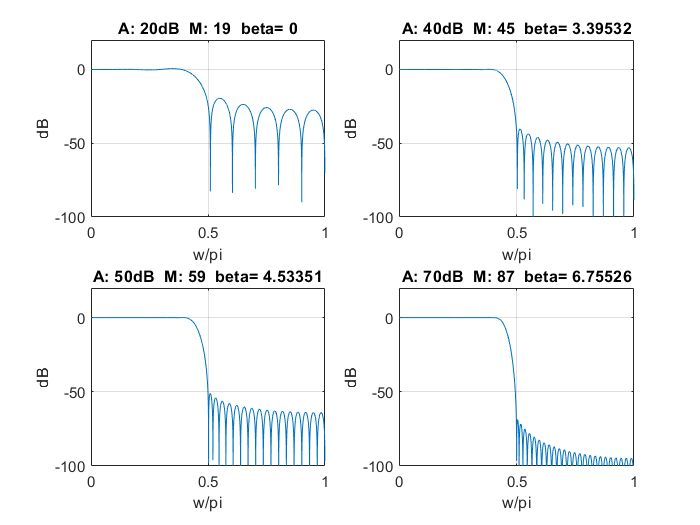

practica23

8. Check that the attenuation in the reject band are those predicted by the Kaiser formulae. 

Annotate below and also check that M and beta are consisten with those obtained by the Kaiser formulae. 

A        20            40            50             70

M       19             45            59            87

$\beta$        0         3.39532    4.53351   6.75526    


$$\begin{array}{l}
M_1 =\frac{A-8}{2\ldotp 285\left(\omega_s -\omega_p \right)}=\frac{21-8}{2\ldotp 285\left(0\ldotp 5\pi -0\ldotp 4\pi \right)}=18\ldotp 1\approx 19\\
M_2 =\frac{A-8}{2\ldotp 285\left(\omega_s -\omega_p \right)}=\frac{40-8}{2\ldotp 285\left(0\ldotp 5\pi -0\ldotp 4\pi \right)}=44\ldotp 57\approx 45\\
M_3 =\frac{A-8}{2\ldotp 285\left(\omega_s -\omega_p \right)}=\frac{50-8}{2\ldotp 285\left(0\ldotp 5\pi -0\ldotp 4\pi \right)}=58\ldotp 5\approx 59\\
M_4 =\frac{A-8}{2\ldotp 285\left(\omega_s -\omega_p \right)}=\frac{70-8}{2\ldotp 285\left(0\ldotp 5\pi -0\ldotp 4\pi \right)}=86\ldotp 36\approx 87
\end{array}$$
      
$$\begin{array}{l}
\beta_1 =0\\
\\
\beta_2 =0\ldotp 5842{\left(A-21\right)}^{0\ldotp 4} +0\ldotp 07886\left(A-21\right)=3\ldotp 39532=3\ldotp 39532\\
\\
\beta_3 =0\ldotp 1102\left(A-8\ldotp 7\right)=4\ldotp 55126\\
\\
\beta_4 =0\ldotp 1102\left(A-8\ldotp 7\right)=6\ldotp 75526
\end{array}$$
